## **Connect and Sample Data from a Hokuyo URG-40LX Laser Scanner.mlx**

*Code to read and analyze data from a ***Hokuyo URG-40LX Laser Scanner. ***Displays a labeled plot of circular targets,*

*and a continous print out of the angle range of holes within the plane of view.*

*Before running, please run UrgBenriPlusV2.2.0 to ensure proper connection has been made to the lidar.*

*Bennett and Tigey: 3/22/22*

disp("Program running...");  %Indicate lidar code starts okay

Program running...


%To avoid incesent error messages in Windows 10, we will temportarily
%disable error warnings
warning('off','all');        %Turn off Matlab warnings

%Lidar is contained in a Matlab serial object, we need to clean up any old
%lidar objects in the workspace to prevent conflicts when we create a new
%one. For Fun-Robo, don't worry about what an object is for now, just
%treat it like a big fancy function.
serialObjs = instrfind;      %Read instrument objects from memory to MATLAB workspace
if ~isempty(serialObjs)      %If there are old objects, close them
    fclose(serialObjs);      %close serial port attatched to old Lidar
    delete(serialObjs);      %delete old lidar objects
end

clc                          %clear command window
clear                        %clear MATLAB workspace

## **Specify which serial port (USB) you have the test bench Hokuyo Lidar plugged into**

%identify and connect to comport
comPort = serialportlist("available");
disp("comPort Identified:")

comPort Identified:


comPort

comPort = "COM6"

## **Connect to Hokuyo Lidar and set its serial communication parameters**

s = serial('port') creates a serial port object s associated with the serial port specified by 'port'. If 'port' does not exist, or if it is in use, you cannot connect the serial port object to the device. 

disp("Conneting to lidar and setting Lidar parameters.");

Conneting to lidar and setting Lidar parameters.


disp("Expect a short delay while setting...")

Expect a short delay while setting...


lidar = serial(comPort,'BaudRate', 115200);  %create a serial port for Lidar
set(lidar,'Timeout',2);                     %set communication link timeout
set(lidar,'InputBufferSize',20000);         %set data input buffer size
set(lidar,'Terminator','LF/CR');            %set data stream terminator for fprintf
                                            %and fscanf. A read operation
                                            %with fgetl, fgets, or fscanf
                                            %completes when the terminator
                                            %value is read
%write a set of Hokuyo parameters to Lidar to configure it
fopen(lidar);                   %connects the serial port object, the lidar
pause(0.3);                     %pauses to allow command to transmit
fprintf(lidar,'SCIP2.0');       %writes string cmd to the lidar
pause(0.3);                     %pause to allow cmd to the lidar
fscanf(lidar);                  %reads ASCII data from the device connected to lidar
fprintf(lidar,'VV');            %pause to allow data to be read
pause(0.3);
fscanf(lidar,'BM');
pause(0.3);
fscanf(lidar);
fprintf(lidar,'MD0044072500');  %dont worry about what commands are sent for now
pause(0.3);
fscanf(lidar);
clc
disp("Lidar Set");

Lidar Set


## Initialize Lidar display

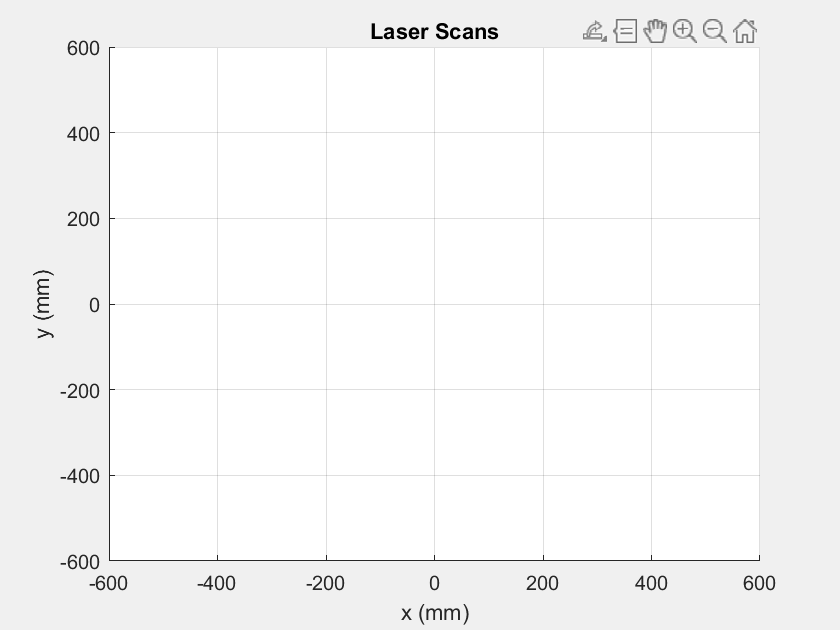

% stand alone figire window

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', 'none', ...
    'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-600 600 -600 600])
xlabel('x (mm)')
ylabel('y (mm)')

## **Sample and Visualize Data**

read Lidar over USB, parse data, create plot of data in 60 sec max loop

**Dont pause and leave this code, needs to complete and then clean shutdown to avoid jamming com link to Lidar**

disp("Read and Plot Lidar Data, type and hold ctrl-c to stop")

Read and Plot Lidar Data, type and hold ctrl-c to stop


Target Detected: Bearing of -78.2927 degrees.

Target Detected: Bearing of -87.4865 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 8.0938 degrees.




Target Detected: Bearing of -78.2716 degrees.

Target Detected: Bearing of -87.5302 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.5304 degrees.

Target Detected: Bearing of -87.6158 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5391 degrees.

Target Detected: Bearing of -87.4998 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.2161 degrees.

Target Detected: Bearing of -87.6873 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -41.173 degrees to -38.0059 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.3282 degrees.

Target Detected: Bearing of -87.9222 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -49.6188 degrees.

Hole Detected: -42.9326 degrees to -38.0059 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -87.8222 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -41.173 degrees to -38.0059 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.8028 degrees.

Target Detected: Bearing of -87.5618 degrees.

Target Detected: Bearing of -18.6838 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.4634 degrees.

Target Detected: Bearing of -87.8165 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -74.6041 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.2704 degrees.

Target Detected: Bearing of -87.7062 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.6355 degrees.

Target Detected: Bearing of -87.9592 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -87.6522 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.5415 degrees.

Target Detected: Bearing of -87.5077 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.4552 degrees.

Target Detected: Bearing of -87.739 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -41.8768 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.3574 degrees.

Target Detected: Bearing of -87.7507 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -87.5686 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.9075 degrees.

Target Detected: Bearing of -87.6752 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.4365 degrees.

Target Detected: Bearing of -87.6383 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.3584 degrees.

Target Detected: Bearing of -88.2211 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 6.3343 degrees.




Target Detected: Bearing of -78.0616 degrees.

Target Detected: Bearing of -87.6334 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.4144 degrees.

Target Detected: Bearing of -87.8755 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.2083 degrees.

Target Detected: Bearing of -87.9097 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.1799 degrees.

Target Detected: Bearing of -87.7416 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.7177 degrees.

Target Detected: Bearing of -87.8928 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.0141 degrees.

Target Detected: Bearing of -87.5849 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.5038 degrees.

Target Detected: Bearing of -87.8442 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.5693 degrees.

Target Detected: Bearing of -87.3925 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -87.7933 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.4199 degrees.

Target Detected: Bearing of -87.8268 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -53.8416 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -87.8292 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.3793 degrees.

Target Detected: Bearing of -87.6503 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.3745 degrees.

Target Detected: Bearing of -87.7041 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.114 degrees.

Target Detected: Bearing of -87.7809 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -53.8416 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -87.5266 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -83.0499 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.5476 degrees.

Target Detected: Bearing of -87.8509 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.4536 degrees.

Target Detected: Bearing of -87.4997 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 8.0938 degrees.




Target Detected: Bearing of -87.5517 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -53.8416 degrees to -49.6188 degrees.

Hole Detected: -41.173 degrees to -38.0059 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.1756 degrees.

Target Detected: Bearing of -87.4658 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.2669 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.3303 degrees.

Target Detected: Bearing of -87.819 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5201 degrees.

Target Detected: Bearing of -87.8135 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.6762 degrees.

Target Detected: Bearing of -87.8798 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.417 degrees.

Target Detected: Bearing of -87.9404 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5325 degrees.

Target Detected: Bearing of -87.7214 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -53.8416 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5924 degrees.

Target Detected: Bearing of -87.6502 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.6632 degrees.

Target Detected: Bearing of -87.659 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.651 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.3085 degrees.

Target Detected: Bearing of -87.7069 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -81.9941 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.0643 degrees.

Target Detected: Bearing of -87.5032 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.317 degrees.

Target Detected: Bearing of -87.6413 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -42.9326 degrees to -38.7097 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.2328 degrees.

Target Detected: Bearing of -87.5925 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 8.0938 degrees.




Target Detected: Bearing of -78.5944 degrees.

Target Detected: Bearing of -87.7991 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.4185 degrees.

Target Detected: Bearing of -87.7321 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.6606 degrees.

Target Detected: Bearing of -87.6433 degrees.

Target Detected: Bearing of -19.2415 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.4291 degrees.

Target Detected: Bearing of -87.4375 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.3486 degrees.

Target Detected: Bearing of -87.7564 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.1862 degrees.

Target Detected: Bearing of -87.1834 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.705 degrees.

Target Detected: Bearing of -87.7794 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5271 degrees.

Target Detected: Bearing of -87.8515 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -41.8768 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.2745 degrees.

Target Detected: Bearing of -87.8252 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.651 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.3706 degrees.

Target Detected: Bearing of -87.75 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -78.4796 degrees.

Target Detected: Bearing of -87.6171 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.

Hole Detected: 111.2023 degrees to 115.7771 degrees.




Target Detected: Bearing of -78.262 degrees.

Target Detected: Bearing of -87.7306 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 5.9824 degrees.

Hole Detected: 103.1085 degrees to 106.6276 degrees.




Target Detected: Bearing of -78.299 degrees.

Target Detected: Bearing of -87.7064 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -42.9326 degrees to -39.0616 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.3343 degrees.




Target Detected: Bearing of -87.3886 degrees.

Target Detected: Bearing of -19.473 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.2604 degrees.

Target Detected: Bearing of -87.6165 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.3013 degrees.

Target Detected: Bearing of -87.5815 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -41.5249 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.3343 degrees.




Target Detected: Bearing of -78.4636 degrees.

Target Detected: Bearing of -87.6588 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.5533 degrees.

Target Detected: Bearing of -87.816 degrees.



Hole Detected: -120 degrees to -110.4985 degrees.

Hole Detected: -109.7947 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.3343 degrees.




Target Detected: Bearing of -87.7646 degrees.

Target Detected: Bearing of -20.7959 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -33.783 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.3656 degrees.

Target Detected: Bearing of -87.7882 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.3799 degrees.

Target Detected: Bearing of -87.4315 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.3192 degrees.

Target Detected: Bearing of -87.9701 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -42.9326 degrees to -39.4135 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.8493 degrees.

Target Detected: Bearing of -87.7184 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.3343 degrees.




Target Detected: Bearing of -78.421 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.7803 degrees.

Target Detected: Bearing of -87.8549 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.6388 degrees.

Target Detected: Bearing of -87.6563 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.1689 degrees.

Target Detected: Bearing of -87.5844 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.1375 degrees.

Target Detected: Bearing of -87.722 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.5696 degrees.

Target Detected: Bearing of -87.7268 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.2596 degrees.

Target Detected: Bearing of -87.7605 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.2669 degrees.

Hole Detected: -41.8768 degrees to -38.0059 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -78.5377 degrees.

Target Detected: Bearing of -87.6099 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.6012 degrees.

Hole Detected: -53.8416 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.5227 degrees.

Target Detected: Bearing of -87.6252 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.6979 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.4811 degrees.

Target Detected: Bearing of -87.7253 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -88.3284 degrees to -82.6979 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.4166 degrees.

Target Detected: Bearing of -87.3444 degrees.



Hole Detected: -119.6481 degrees to -102.7566 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 6.6862 degrees.




Target Detected: Bearing of -78.68 degrees.

Target Detected: Bearing of -87.5039 degrees.



Hole Detected: -120 degrees to -111.9062 degrees.

Hole Detected: -87.9765 degrees to -82.346 degrees.

Hole Detected: -74.2522 degrees to -70.3812 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of 1.4824 degrees.

Target Detected: Bearing of -78.5156 degrees.

Target Detected: Bearing of -87.817 degrees.



Hole Detected: -120 degrees to -99.5894 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.39 degrees.




Target Detected: Bearing of -2.8192 degrees.

Target Detected: Bearing of -78.2538 degrees.

Target Detected: Bearing of -88.1827 degrees.

Target Detected: Bearing of -22.4256 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -100.2933 degrees to -92.9032 degrees.

Hole Detected: -73.9003 degrees to -70.3812 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -78.1907 degrees.

Target Detected: Bearing of -88.0116 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -91.1437 degrees to -85.8651 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -49.6188 degrees.

Hole Detected: -42.5806 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -9.5835 degrees.

Target Detected: Bearing of -16.3533 degrees.

Target Detected: Bearing of -78.3114 degrees.

Target Detected: Bearing of -87.5929 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -90.088 degrees to -83.7537 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -50.3226 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -7.2645 degrees.

Target Detected: Bearing of -16.1112 degrees.

Target Detected: Bearing of -78.9601 degrees.

Target Detected: Bearing of -87.3096 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -90.4399 degrees to -84.8094 degrees.

Hole Detected: -80.5865 degrees to -75.3079 degrees.

Hole Detected: -59.824 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -50.3226 degrees.

Hole Detected: -34.1349 degrees to -18.2991 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.




Target Detected: Bearing of -7.1039 degrees.

Target Detected: Bearing of -16.4597 degrees.

Target Detected: Bearing of -78.3031 degrees.

Target Detected: Bearing of -87.6824 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -90.088 degrees to -83.7537 degrees.

Hole Detected: -81.6422 degrees to -75.3079 degrees.

Hole Detected: -60.176 degrees to -50.3226 degrees.

Hole Detected: -42.5806 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -9.9572 degrees.

Target Detected: Bearing of -16.6448 degrees.

Target Detected: Bearing of -87.6682 degrees.



Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -89.7361 degrees to -82.346 degrees.

Hole Detected: -77.7713 degrees to -74.6041 degrees.

Hole Detected: -59.824 degrees to -55.6012 degrees.

Hole Detected: -54.5455 degrees to -50.3226 degrees.

Hole Detected: -41.8768 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.7419 degrees.




Target Detected: Bearing of -16.9071 degrees.

Target Detected: Bearing of -77.9826 degrees.

Target Detected: Bearing of -87.551 degrees.



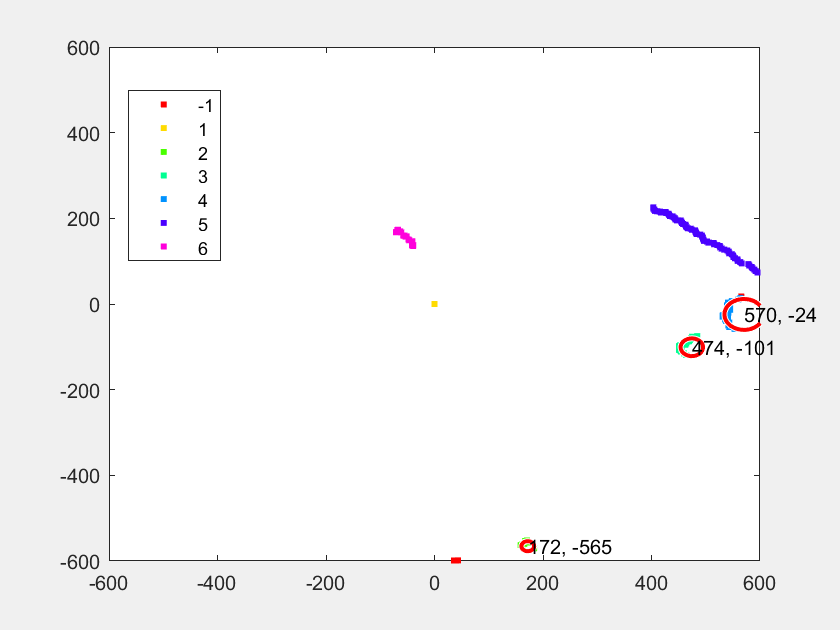

Hole Detected: -120 degrees to -102.7566 degrees.

Hole Detected: -89.3842 degrees to -74.6041 degrees.

Hole Detected: -60.176 degrees to -55.2493 degrees.

Hole Detected: -54.5455 degrees to -50.3226 degrees.

Hole Detected: -42.5806 degrees to -38.3578 degrees.

Hole Detected: -34.1349 degrees to -17.9472 degrees.

Hole Detected: 2.1114 degrees to 7.0381 degrees.





angles = (-120:240/682:120-240/682) * pi / 180; % Convert sensor steps to angles
tStart = tic;                                   %Start timer
iscan = 0;

while (iscan == 0)                              % countinuous loop

    [A] = FunRoboLidarScan(lidar);              % actual scan data
    data = filter(angles, A, 600);              %filtered scan data
    data2 = polCart(data);                      %convert to cartesian coords
    
    findObjects(data2');                        %identify objects in the points

    readout(A, angles, 600, 3);                 %print holes 3 degrees across at 600mm

    pause(0.2)                                  % allow serial to keep up
    
    tElapsed = toc(tStart);                     % measure time since experiment start
    if (tElapsed > 60)                          % if gone too long, stop loop
        iscan = 1;
    end

end

## Disconnect Lidar

Please always run this section so the lidar doesnt become sentient 

%disconnect lidar
fprintf(lidar, 'QT');
fclose(lidar);
clear lidar;
warning('on');
disp("The lidar has successfully been terminated.")

The lidar has successfully been terminated.


## Functions

function [filtered] = filter(angles, A, cutoffDist)
    %Filters data to exclude points outside of cut off distance 
    %Takes A in mm, angles in rad, cut off distance in mm
    %Returns filtered data matrix
    
    A(A > cutoffDist) = 0;
    A(A < 40) = 0;
    
    filtered = [angles; A];
end

function data = polCart(polData)
    %converts data to cartesian coordinates
    %takes polar data, returns cartesian coordinate matrix

    X = polData(2, :).*cos(polData(1, :));          % Trig to find x-coord
    Y = polData(2, :).*sin(polData(1, :));          % Trig to find y-coord 
    data = [X; Y];
            
end

function [rangescan]=FunRoboLidarScan(lidar)
%Get a LIDAR Scan
%Returns a range vector of 682 elements after a Lidar Scan from min step
% to max step. Range Values correspond from -120 to +120 degrees.
% Author- Shikhar Shrestha, IIT Bhubaneswar
% Lightly modified by Olin Studnet 2019

proceed=0;
fprintf(lidar,'GD0044072500');

while (proceed==0)
    if lidar.BytesAvailable >= 2134
        data = fscanf(lidar,'%c',2134);
        proceed = 1;
    end
end

i = find(data == data(13));
rangedata=data(i(3)+1:end-1);

for j=0:31
    onlyrangedata((64*j)+1:(64*j)+64)=rangedata(1+(66*j):64+(66*j));
end

j=0;

for i=1:floor(numel(onlyrangedata)/3)
    encodeddist(i,:)=[onlyrangedata((3*j)+1) onlyrangedata((3*j)+2) onlyrangedata((3*j)+3)];
    j=j+1;
end

for k=1:size(encodeddist,1)
    rangescan(k)=decodeSCIP(encodeddist(k,:));
end

end

function rangeval=decodeSCIP(rangeenc)
% Function to decode range information transmitted using SCIP2.0 protocol.
% Works for only two and three bit encoding.
% Author- Shikhar Shrestha, IIT Bhubaneswar

% Check for 2 or 3 Character Encoding
if rangeenc(1)=='0' && rangeenc(2)=='0' && rangeenc(3)=='0'
    rangeval=0;
    return;
end
if rangeenc(1)=='0'
    dig1=((rangeenc(2)-'!')+33);
    dig2=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    rangeval=bin2dec([dig1bin dig2bin]);
    return;
else
    dig1=((rangeenc(1)-'!')+33);
    dig2=((rangeenc(2)-'!')+33);
    dig3=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig3sub=dig3-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    dig3bin=dec2bin(dig3sub,6);
    rangeval=bin2dec([dig1bin dig2bin dig3bin]);
    return;
    
end
    
end

function [xo, yo, R] = circle_fit(x,y)
% Identifies circles within sets of points
% Takes x coordinates and y coordinates
% Outputs circle x coordinate center, circle y coordinate\
% center, and circle radius
x = x(:);
y = y(:);

% Fit a circle to the data through least squares calc
A = [-2*x -2*y ones(length(x),1)];
x = A\-(x.^2+y.^2);

%pull x coord, y coord, and calc r
xo=x(1);
yo=x(2);
R = sqrt(  xo.^2 + yo.^2  - x(3));

end

function [objects, circles] = findObjects(X)
    % run DBSCAN algorithm for object recognition
    idx = dbscan(X, 20, 5);
    
    %Label each point with what cluster it belongs to
    objects = [X(:,1), X(:,2), idx];

    %initialixze circles matrix
    circles = [];

    %cycle through each object
    for i = 1:max(idx)
        %select one group of points by idx value
        object = objects(objects(:, 3) == i, :);  
        %calculate linear fit of points in the object
        mdl = fitlm(object(:,1), object(:,2));
        %calculate circle fir of points in the object
        [xc, yc, r] = circle_fit(object(:,1), object(:,2));
        %if sufficiently circular, recognize it as a circle
        if(r < 130 && r > 10 && mdl.Rsquared.Ordinary < 0.6)
            %assign circle's values to circle matrix
            circles = [circles; xc yc r];
        end
    end

    hold on
    clf
    %plot x coor, y coord, and object identity
    gscatter(objects(:,1), objects(:, 2), objects(:,3))

    %plot -600 to 600 mm for x and y
    range = 600;
    axis([-range, range, -range, range])

    %plot each circle, and label with x and y coord of centeroid
    for i = 1:size(circles,1)
        viscircles([circles(i, 1) circles(i,2)], circles(i,3));
        text(circles(i, 1), circles(i,2), strcat(num2str(int16(circles(i,1))), ...
            ", ", num2str(int16(circles(i,2)))));
        X = circles(i, 1);
        Y = circles(i, 2);
        ang = atand(X/Y);
        targetRange = ['Target Detected: Bearing of ', num2str(ang), ' degrees.'];
        disp(targetRange);
        fprintf('\n');        %new line
    end
    hold off
        
end

function readout(A, angles, cutOffDist, cutOffAng)
%display position and bearing of holes identified by the lidar.
%Takes position data, angle array, cut off distance, and cut off
%angle as inputs, and displays range of angles that are "open" 
%for the robot
%Bennett Taylor Rev 1

    %initialize holeVals matrix, same length as measures positons
    holeVals = zeros(1,size(A,2));

    %for each position
    for i = 1:size(A,2)
        
        %if the distance is above the cut off, store its angle
        if A(1,i) >= 0 && A(1,i) >= cutOffDist
            holeVals(1,i) = angles(1,i);

        % when a non-hole value is found
        elseif A(1,i) >= 0 && A(1,i) < cutOffDist
            holeVals(holeVals == 0) = [];       %purge unused columns
            Maxim = max(holeVals,[],'all');     %ident max angle
            maximDeg = rad2deg(Maxim);          %convert to degrees
            Minim = min(holeVals,[],'all');     %ident min angle
            minimDeg = rad2deg(Minim);          %convert to degrees
            holeRange = ['Hole Detected: ', num2str(minimDeg), ' degrees to ', num2str(maximDeg),' degrees.'];
            if (abs(maximDeg-minimDeg) >= cutOffAng) %if the hole is big enough
              disp(holeRange);      %display the hole range
              fprintf('\n');        %new line
            end

            holeVals = zeros(1,size(A,2)); %reset holeVals matrix
        end
        
    end
    
    fprintf('\n');           %new line for the next iteration
end       